# Teoria delle strutture - PROBLEMA 6

% Arco di forma parabolica schematizzato come una trave flessibile (e inestensibile)
% ad asse curvilineo
% di rigidezza flessionale EJ.

## Clear workspace and close any open windows

clear all
close all

## SOLUZIONE PUNTO 1 

% 1) Mostrare che le sollecitazioni nell’arco, nel caso in cui sia soggetto esclusivamente al
% carico distribuito d’intensità uniforme p, mostrato nella figura a sinistra, si riducono al solo
% sforzo normale, variabile lungo la linea d’asse. Determinare l’andamento dello sforzo
% normale.

## SIMBOLICO

syms L a b c z real
assume(L>0 )
f=L/2;
% assumo f come un parametro che dipende da L
% altrimenti il software impiega troppo tempo a risolvere eventuali integrali

## Determino l'equazione della nostra parabola

F(z)=a*z^2+b*z+c % Equazione della parabola 

$$F(z) = a\,z^{2}+b\,z+c$$

% SISTEMA D'EQUAZIONI PER TROVARE LA FUNZIONE DELLA PARABOLA DATA 
delta=b^2-4*a*c;
% fisso che la cordinata x del vertice della parabloa passi per un determinato punto
E1=-b/(2*a)==L/2; 
% fisso che la cordinata y del vertice della parabloa passi per un determinato punto
E2=-delta/(4*a)==f;
% fisso che la èarabola passi per punto A ''il nostro vincolo'' 
E3=F(0)==0; 
% Risolvo il sistema
S=solve([E1 E2 E3],[a b c]);
a_1=S.a(1)

$$a\_1 = -\frac{2}{L}$$

b_1=S.b(1)

$$b\_1 = 2$$

c_1=S.c(1)

$$c\_1 = 0$$

% L'equazione della parabola diventa:
G(z)=simplify(subs(F,[a b c],[a_1 b_1 c_1]))

$$G(z) = 2\,z-\frac{2\,z^{2}}{L}$$

## Derivate della funzione parabolica

D1=simplify(diff(G,z)) % Derivata prima 

$$D1(z) = 2-\frac{4\,z}{L}$$

D2=simplify(diff(D1,z)) % Derivata seconda 

$$D2(z) = -\frac{4}{L}$$

## PARAMETRIZZAZIONE DELLA CURVA

tan=D1              % porto tang_θ in funzione di z

$$tan(z) = 2-\frac{4\,z}{L}$$

ds=simplify(sqrt(1+D1^2)) % porto ds in funzione di z 

$$ds(z) = \sqrt{{\left(\frac{4\,z}{L}-2\right)}^{2}+1}$$

SIN(z)=D1/ds        % porto sin_θ in funzione di z 

$$SIN(z) = -\frac{\frac{4\,z}{L}-2}{\sqrt{{\left(\frac{4\,z}{L}-2\right)}^{2}+1}}$$

COS(z)=1/ds         % porto cos_θ in funzione di z

$$COS(z) = \frac{1}{\sqrt{{\left(\frac{4\,z}{L}-2\right)}^{2}+1}}$$

## SISTEMA FO

syms VA VC HA p real
% equazione alla traslazione orizzontale 
E4=(VA-VC)*COS(0)-HA*SIN(0)==0

$$E4 = \frac{\sqrt{5}\,\left(\mathrm{VA}-\mathrm{VC}\right)}{5}-\frac{2\,\sqrt{5}\,\mathrm{HA}}{5}=0$$

% equazione alla traslazione verticale 
E5=L*p-HA*COS(0)-(VA +VC)*SIN(0)==0 

$$E5 = L\,p-\frac{\sqrt{5}\,\mathrm{HA}}{5}-\frac{2\,\sqrt{5}\,\left(\mathrm{VA}+\mathrm{VC}\right)}{5}=0$$

% equazione alla rotazione in A 
E6=L*VC*SIN(0)-(L^2)*p/2==0;
% Risolvo il sistema
SO=solve([E4 E5 E6],[VA VC HA]);
HA0=SO.HA(1)

$$HA0 = 0$$

VA0=SO.VA(1)

$$VA0 = \frac{\sqrt{5}\,L\,p}{4}$$

VC0=SO.VC(1)

$$VC0 = \frac{\sqrt{5}\,L\,p}{4}$$

## Momento in F0

% Momento
M0(z)=simplify(-((p*z^2)/2)+VA0*SIN(0)*(z)-VA0*COS(0)*G(z))

$$M0(z) = 0$$

% (poichè il momento è nullo , anche il taglio sarà nullo essendo T=M')
% mi riduco al caso di solo N(z)

## SISTEMA F1

% equazione alla traslazione orizzontale 
E7=VA*COS(0)-HA*SIN(0)-VC*COS(0)+1*SIN(0)==0;
% equazione alla traslazione verticale 
E8=-VA*SIN(0)-VC*SIN(0)-HA*COS(0)-1*COS(0)==0;
% equazione alla rotazione in A 
E9=VC*SIN(0)*L+1*COS(0)*L==0;
% Risolvo il sistema
S1=solve([E7 E8 E9],[VA VC HA]);
HA1=S1.HA(1)

$$HA1 = 1$$

VA1=S1.VA(1)

$$VA1 = -\frac{1}{2}$$

VC1=S1.VC(1)

$$VC1 = -\frac{1}{2}$$

## Momento in F1

% Momento in F1 
M1(z)=simplify(VA1*SIN(0)*z-VA1*COS(0)*G(z)+1*COS(0)*(z)+1*SIN(0)*G(z))

$$M1(z) = \sqrt{5}\,\left(z-\frac{z^{2}}{L}\right)$$

## MULLER-BRESLAU

syms E J X1 real
assume(E>0 & J>0)
Lv10=simplify(int(M1(z)*M0(z)/(E*J)*ds,z,0,L))

$$Lv10 = 0$$

Lv11 =int(M1(z)^2/(E*J)*ds,z,0,L); 
n10 =Lv10 ; n11 =Lv11;
n1=n10+X1*n11==0;
X1=(-n10/n11)

$$X1 = 0$$

## CALCOLO DELLE REAZIONI VINCOLARI 

VAE=VA0+X1*VA1 % VA esatto

$$VAE = \frac{\sqrt{5}\,L\,p}{4}$$

HAE=HA0+X1*HA1 % HA esatto 

$$HAE = 0$$

## CALCOLO DELLE CDS ESATTE

M1E=M0(z)+X1*M1(z) % Momento esatto

$$M1E = 0$$

N1E=simplify(-VAE*(COS(0))/COS(z)) % Forza normale esatta

$$N1E = -\frac{L\,p\,\sqrt{{\left(\frac{4\,z}{L}-2\right)}^{2}+1}}{4}$$

## SOLUZIONE PUNTO 2

%2) Determinare le sollecitazioni nell’arco nel caso in cui, oltre al carico verticale p, sia
%presente anche un carico distribuito in direzione orizzontale, d’intensità pari a q

% Ora mi limito a calcolare il caso con la sola forza orizzontale,
% (poichè ho già calcolato il caso con la forza verticale)
% Posso poi usare la sovrapposizione degli effetti per ricavare la soluzione del punto 2

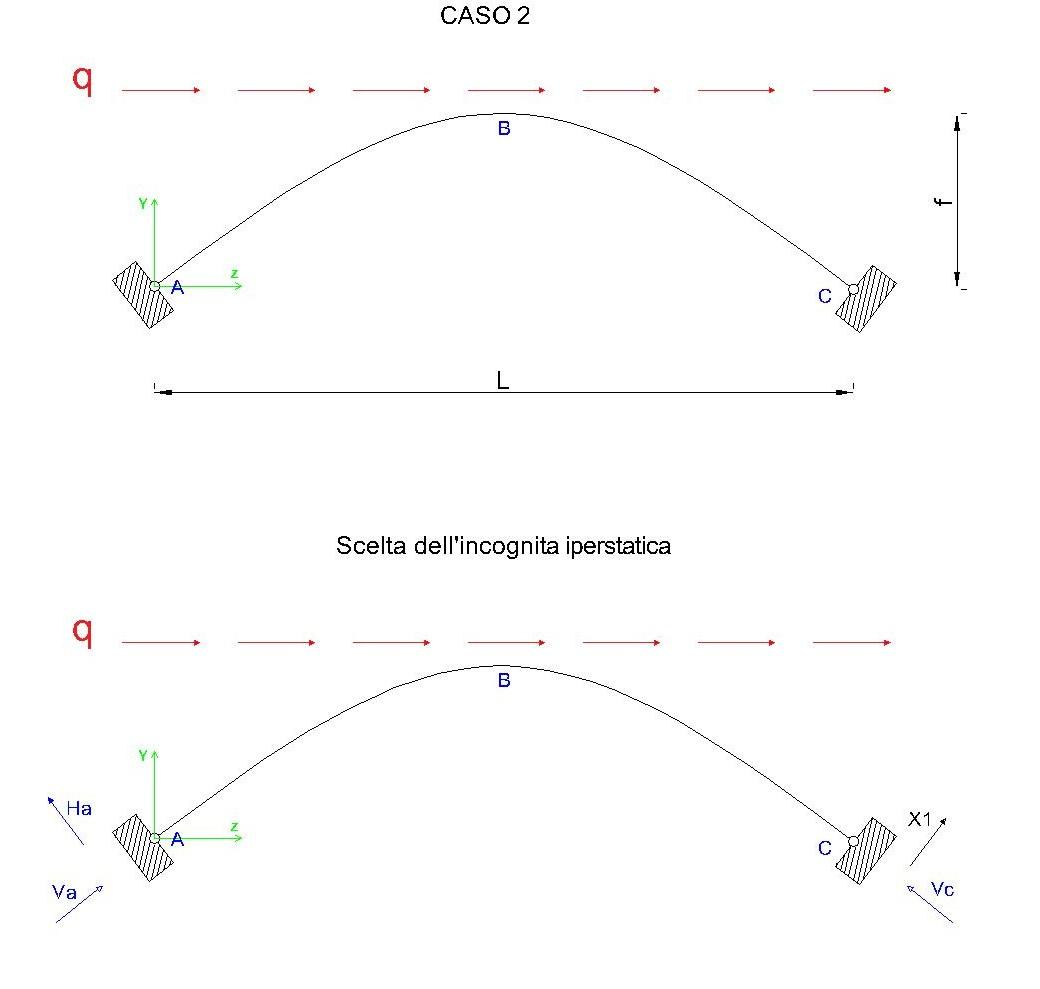

## SISTEMA F0

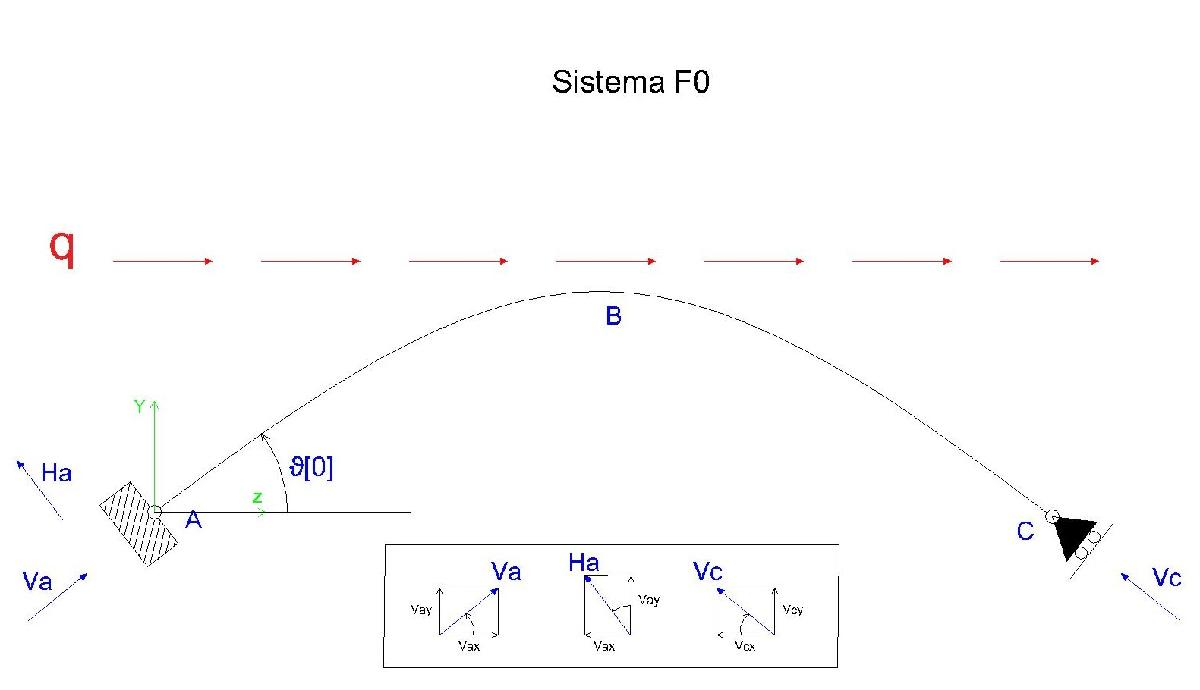

syms q real
assume(q>0)
% equazione alla traslazione orizzontale 
E10=(VA-VC)*COS(0)-HA *SIN(0)+q*L==0;
% equazione alla traslazione verticale 
E11=-HA*COS(0)-(VA +VC)*SIN(0)==0;
%  equazione alla rotazione in A 
E12=L*VC*SIN(0)-q*L*f==0;
S3=solve([E10 E11 E12],[VA VC HA]);
HA2O=S3.HA(1)

$$HA2O = \frac{\sqrt{5}\,L\,q}{5}$$

VA2O=S3.VA(1)

$$VA2O = -\frac{7\,\sqrt{5}\,L\,q}{20}$$

VC2O=S3.VC(1)

$$VC2O = \frac{\sqrt{5}\,L\,q}{4}$$

## Momento in F0

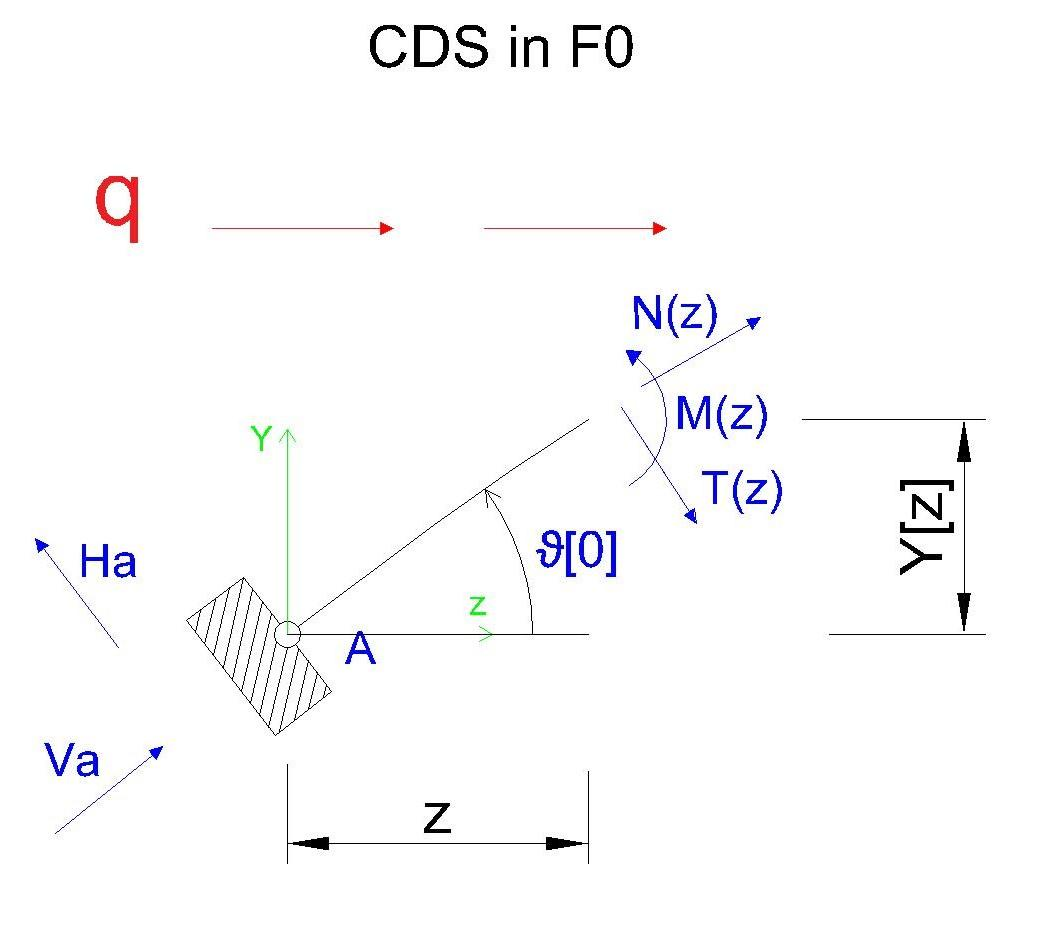

% Momento 
M20(z)=simplify(VA2O*SIN(0)*z-VA2O*COS(0)*G(z)+HA2O*COS(0)*z+HA2O*SIN(0)*G(z)+q*z*(f-G(z)))

$$M20(z) = \frac{q\,z\,\left(3\,L^{2}-7\,L\,z+4\,z^{2}\right)}{2\,L}$$

## SISTEMA F1

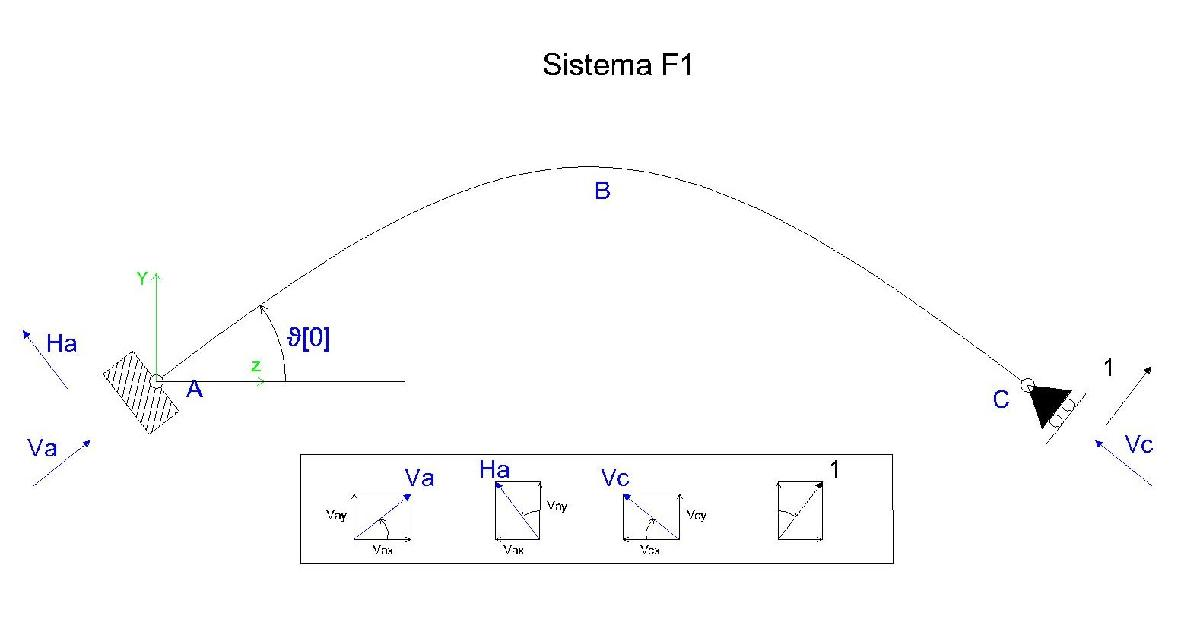

% equazione alla traslazione orizzontale 
E13=VA*COS(0)-HA*SIN(0)-VC*COS(0)+1*SIN(0)==0;
% equazione alla traslazione verticale 
E14=-VA*SIN(0)-VC*SIN(0)-HA*COS(0)-1*COS(0)==0;
% equazione alla rotazione in A 
E15=VC*SIN(0)*L+1*COS(0)*L==0;
S4=solve([E13 E14 E15],[VA VC HA]);
HA21=S3.HA(1)

$$HA21 = \frac{\sqrt{5}\,L\,q}{5}$$

VA21=S3.VA(1)

$$VA21 = -\frac{7\,\sqrt{5}\,L\,q}{20}$$

VC21=S3.VC(1)

$$VC21 = \frac{\sqrt{5}\,L\,q}{4}$$

## Momento in F1

M21(z)=simplify(VA21*SIN(0)*z-VA21*COS(0)*G(z)+1*COS(0)*z+1*SIN(0)*G(z))

$$M21(z) = -\frac{z\,\left(8\,\sqrt{5}\,z-10\,\sqrt{5}\,L+7\,L\,q\,z\right)}{10\,L}$$

## MULLER-BRESLAU

Lv210=simplify(int(M21(z)*M20(z)/(E*J)*ds,z,0,L))

$$Lv210 = \begin{array}{l} \frac{L^{4}\,q\,\left(5328\,\sqrt{5}\,\sigma_{2}-5328\,\sqrt{5}\,\sigma_{1}+2268\,\sqrt{5}\,L\,q+3423\,L\,q\,\sigma_{1}-3423\,L\,q\,\sigma_{2}+13760\right)}{983040\,\text{E}\,J}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

Lv211=simplify(int(M21(z)^2/(E*J)*ds,z,0,L))

$$Lv211 = \begin{array}{l} \frac{L^{3}\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}{4915200\,\text{E}\,J}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

n210=Lv210; n211 =Lv211;
% n21=n210+X21*n211==0;
X21=simplify(-n210/n211)

$$X21 = \begin{array}{l} -\frac{5\,L\,q\,\left(5328\,\sqrt{5}\,\sigma_{2}-5328\,\sqrt{5}\,\sigma_{1}+2268\,\sqrt{5}\,L\,q+3423\,L\,q\,\sigma_{1}-3423\,L\,q\,\sigma_{2}+13760\right)}{298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

## REAZIONI VINCOLARI ESATTE

VA2E=simplify(VA2O+simplify(X21*VA21)) % VA esatto 

$$VA2E = \begin{array}{l} \frac{7\,\sqrt{5}\,L^{2}\,q^{2}\,\left(5328\,\sqrt{5}\,\sigma_{2}-5328\,\sqrt{5}\,\sigma_{1}+2268\,\sqrt{5}\,L\,q+3423\,L\,q\,\sigma_{1}-3423\,L\,q\,\sigma_{2}+13760\right)}{4\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}-\frac{7\,\sqrt{5}\,L\,q}{20}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

HA2E=simplify(HA2O+simplify(X21*HA21)) % HA esatto 

$$HA2E = \begin{array}{l} \frac{\sqrt{5}\,L\,q}{5}-\frac{\sqrt{5}\,L^{2}\,q^{2}\,\left(5328\,\sqrt{5}\,\sigma_{2}-5328\,\sqrt{5}\,\sigma_{1}+2268\,\sqrt{5}\,L\,q+3423\,L\,q\,\sigma_{1}-3423\,L\,q\,\sigma_{2}+13760\right)}{298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

## CDS ESATTE

M2E=simplify(M20(z)+simplify(X21*M21(z))) % Momento

$$M2E = \begin{array}{l} \frac{q\,z\,\left(3\,L^{2}-7\,L\,z+4\,z^{2}\right)}{2\,L}+\frac{q\,z\,\left(8\,\sqrt{5}\,z-10\,\sqrt{5}\,L+7\,L\,q\,z\right)\,\left(5328\,\sqrt{5}\,\sigma_{2}-5328\,\sqrt{5}\,\sigma_{1}+2268\,\sqrt{5}\,L\,q+3423\,L\,q\,\sigma_{1}-3423\,L\,q\,\sigma_{2}+13760\right)}{2\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

% FORZA NORMALE E TAGLIO 
syms N2 T2 real
E16=N2*COS(z)+T2*SIN(z)+VA2E*COS(0)-HA2E*SIN(0)+q*z==0;
E17=T2*COS(z)-N2*SIN(z)-HA2E*COS(0)-VA2E*SIN(0)==0;
S6=solve([E16 E17],[N2,T2]);

N2E=simplify(S6.N2(1))

$$N2E = \begin{array}{l} \frac{L\,q\,\left(1805440\,\sqrt{5}\,L-3095040\,\sqrt{5}\,z-6254080\,L^{2}\,q-1044960\,L\,\sigma_{1}+1044960\,L\,\sigma_{2}+1791360\,z\,\sigma_{1}-1791360\,z\,\sigma_{2}+1204028\,\sqrt{5}\,L^{3}\,q^{2}+10583680\,L\,q\,z-101577\,L^{3}\,q^{2}\,\sigma_{1}+101577\,L^{3}\,q^{2}\,\sigma_{2}+139902\,L^{2}\,q^{2}\,z\,\sigma_{1}-139902\,L^{2}\,q^{2}\,z\,\sigma_{2}+303744\,\sqrt{5}\,L^{2}\,q\,\sigma_{1}-303744\,\sqrt{5}\,L^{2}\,q\,\sigma_{2}-2086728\,\sqrt{5}\,L^{2}\,q^{2}\,z-467424\,\sqrt{5}\,L\,q\,z\,\sigma_{1}+467424\,\sqrt{5}\,L\,q\,z\,\sigma_{2}\right)}{2\,\sqrt{5\,L^{2}-16\,L\,z+16\,z^{2}}\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

T2E=simplify(S6.T2(1))

$$T2E = \begin{array}{l} \frac{2\,q\,\left(597120\,z^{2}\,\sigma_{2}-597120\,z^{2}\,\sigma_{1}+257920\,\sqrt{5}\,L^{2}-893440\,L^{3}\,q+1031680\,\sqrt{5}\,z^{2}-149280\,L^{2}\,\sigma_{1}+149280\,L^{2}\,\sigma_{2}+172004\,\sqrt{5}\,L^{4}\,q^{2}-1289600\,\sqrt{5}\,L\,z-14511\,L^{4}\,q^{2}\,\sigma_{1}+14511\,L^{4}\,q^{2}\,\sigma_{2}-3436160\,L\,q\,z^{2}+4398400\,L^{2}\,q\,z+746400\,L\,z\,\sigma_{1}-746400\,L\,z\,\sigma_{2}+710696\,\sqrt{5}\,L^{2}\,q^{2}\,z^{2}+55440\,L^{3}\,q^{2}\,z\,\sigma_{1}-55440\,L^{3}\,q^{2}\,z\,\sigma_{2}-23814\,L^{2}\,q^{2}\,z^{2}\,\sigma_{1}+23814\,L^{2}\,q^{2}\,z^{2}\,\sigma_{2}+43392\,\sqrt{5}\,L^{3}\,q\,\sigma_{1}-43392\,\sqrt{5}\,L^{3}\,q\,\sigma_{2}-871360\,\sqrt{5}\,L^{3}\,q^{2}\,z+120288\,\sqrt{5}\,L\,q\,z^{2}\,\sigma_{1}-120288\,\sqrt{5}\,L\,q\,z^{2}\,\sigma_{2}-190320\,\sqrt{5}\,L^{2}\,q\,z\,\sigma_{1}+190320\,\sqrt{5}\,L^{2}\,q\,z\,\sigma_{2}\right)}{\sqrt{5\,L^{2}-16\,L\,z+16\,z^{2}}\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

## SOVRAPPOSIZIONE DEGLI EFFETTI

MF=M2E % momento

$$MF = \begin{array}{l} \frac{q\,z\,\left(3\,L^{2}-7\,L\,z+4\,z^{2}\right)}{2\,L}+\frac{q\,z\,\left(8\,\sqrt{5}\,z-10\,\sqrt{5}\,L+7\,L\,q\,z\right)\,\left(5328\,\sqrt{5}\,\sigma_{2}-5328\,\sqrt{5}\,\sigma_{1}+2268\,\sqrt{5}\,L\,q+3423\,L\,q\,\sigma_{1}-3423\,L\,q\,\sigma_{2}+13760\right)}{2\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

NF=simplify(N1E+N2E) % forza normale

$$NF = \begin{array}{l} \frac{L\,q\,\left(1805440\,\sqrt{5}\,L-3095040\,\sqrt{5}\,z-6254080\,L^{2}\,q-1044960\,L\,\sigma_{1}+1044960\,L\,\sigma_{2}+1791360\,z\,\sigma_{1}-1791360\,z\,\sigma_{2}+1204028\,\sqrt{5}\,L^{3}\,q^{2}+10583680\,L\,q\,z-101577\,L^{3}\,q^{2}\,\sigma_{1}+101577\,L^{3}\,q^{2}\,\sigma_{2}+139902\,L^{2}\,q^{2}\,z\,\sigma_{1}-139902\,L^{2}\,q^{2}\,z\,\sigma_{2}+303744\,\sqrt{5}\,L^{2}\,q\,\sigma_{1}-303744\,\sqrt{5}\,L^{2}\,q\,\sigma_{2}-2086728\,\sqrt{5}\,L^{2}\,q^{2}\,z-467424\,\sqrt{5}\,L\,q\,z\,\sigma_{1}+467424\,\sqrt{5}\,L\,q\,z\,\sigma_{2}\right)}{2\,\sqrt{5\,L^{2}-16\,L\,z+16\,z^{2}}\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}-\frac{L\,p\,\sqrt{{\left(\frac{4\,z}{L}-2\right)}^{2}+1}}{4}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

TF=simplify(T2E) % taglio

$$TF = \begin{array}{l} \frac{2\,q\,\left(597120\,z^{2}\,\sigma_{2}-597120\,z^{2}\,\sigma_{1}+257920\,\sqrt{5}\,L^{2}-893440\,L^{3}\,q+1031680\,\sqrt{5}\,z^{2}-149280\,L^{2}\,\sigma_{1}+149280\,L^{2}\,\sigma_{2}+172004\,\sqrt{5}\,L^{4}\,q^{2}-1289600\,\sqrt{5}\,L\,z-14511\,L^{4}\,q^{2}\,\sigma_{1}+14511\,L^{4}\,q^{2}\,\sigma_{2}-3436160\,L\,q\,z^{2}+4398400\,L^{2}\,q\,z+746400\,L\,z\,\sigma_{1}-746400\,L\,z\,\sigma_{2}+710696\,\sqrt{5}\,L^{2}\,q^{2}\,z^{2}+55440\,L^{3}\,q^{2}\,z\,\sigma_{1}-55440\,L^{3}\,q^{2}\,z\,\sigma_{2}-23814\,L^{2}\,q^{2}\,z^{2}\,\sigma_{1}+23814\,L^{2}\,q^{2}\,z^{2}\,\sigma_{2}+43392\,\sqrt{5}\,L^{3}\,q\,\sigma_{1}-43392\,\sqrt{5}\,L^{3}\,q\,\sigma_{2}-871360\,\sqrt{5}\,L^{3}\,q^{2}\,z+120288\,\sqrt{5}\,L\,q\,z^{2}\,\sigma_{1}-120288\,\sqrt{5}\,L\,q\,z^{2}\,\sigma_{2}-190320\,\sqrt{5}\,L^{2}\,q\,z\,\sigma_{1}+190320\,\sqrt{5}\,L^{2}\,q\,z\,\sigma_{2}\right)}{\sqrt{5\,L^{2}-16\,L\,z+16\,z^{2}}\,\left(298560\,\sigma_{2}-298560\,\sigma_{1}-1718080\,L\,q+515840\,\sqrt{5}+355348\,\sqrt{5}\,L^{2}\,q^{2}-11907\,L^{2}\,q^{2}\,\sigma_{1}+11907\,L^{2}\,q^{2}\,\sigma_{2}+60144\,\sqrt{5}\,L\,q\,\sigma_{1}-60144\,\sqrt{5}\,L\,q\,\sigma_{2}\right)}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{L\,\left(\sqrt{5}-2\right)}{4}\right)\\ \sigma_{2}=\log\left(\frac{L\,\left(\sqrt{5}+2\right)}{4}\right) \end{array}$$

## PUNTO 3 & 4

% 3) Assumendo che lo spessore dell’arco sia pari a h = l/20, determinare il valore di q in
%corrispondenza del quale la curva delle pressioni risulta tangente all’estradosso o
%all’intradosso dell’arco. Per il valore di q così determinato, tracciare l’andamento della
%curva delle pressioni.

%4) Determinare il massimo valore di q in corrispondenza del quale tutte le sezioni
%trasversali dell’arco sono soggette a tensioni di compressione (o, al più, a tensioni nulle).
%Nel calcolo, assumere h = l/20. Per il valore di q così determinato, tracciare l’andamento
%della curva delle pressioni.

## Eccentricità

e=MF/NF;
% se faccio la tangente della funzione e, posso valutare se è uguale alla tangente dell'intradosso o estradosso.
% devo però fissare anche il punto in cui questa uguaglianza deve verificarsi.
% E' impossibile che questa uguaglianza sia verificata.
% E' bene analizzare tale curva numericamente.